clear;

Define the function

f = @(x) sin(2*pi*x);

Plot the function

x_plot = 0:.01:1;
figure,
plot(x_plot, f(x_plot), 'g'),
xlabel("x"), ylabel("t"),
axis square;

Create some points

N = 10;
x = linspace(0, 1, N)';

Create a random Guassian distribution for add some noise to data

std = .3;
gaussian = normrnd(0, std, N, 1);

Evaluate target vector adding some noise

t = f(x) + gaussian;

Plot the target values above the function

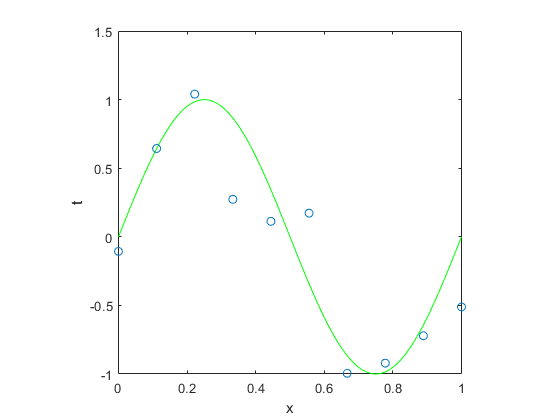

hold on,
plot(x, t, 'o');

Generate the model resolving the linear system generated from the partial derivatives of the polynomial with order M

M = 0:9;
W = min_least_squares(M, x, t);

Creating the data

training = predict(10, W);
test = predict(100, W);

Calculating the RMS errors

gaussian = normrnd(0, std, 100, 1);
t_test = f(test.x) + gaussian; % Generate the target vector for test data
training.rms = zeros(length(W), 1);
test.rms = zeros(length(W), 1);
for wi=1:length(W)
    training.rms(wi) = rmse(training.y(:, wi), t);
    test.rms(wi) = rmse(test.y(:, wi), t_test);
end

Plots of polynomials having various orders M, shown as red curves, fitted to the data set shown in Figure 1.2

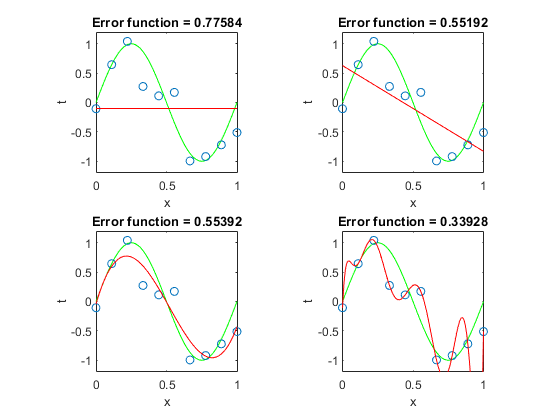

idx_w = [0 1 3 9] + 1;
figure,
for wi=1:length(idx_w)
    subplot(2, 2, wi),
    plot(x_plot, f(x_plot), 'g'),
    xlabel("x"), ylabel("t"),
    axis square;
    
    hold on,
    plot(x, t, 'o');
    
    hold on,
    plot(x_plot, pol(x_plot, W{idx_w(wi)}), 'r'),
    ylim([-1.2 1.2]);
    
    title(['Error function = ' num2str(test.rms(wi))]);
end

Plot a comparison of errors between test and training data to shor the over-fitting problem

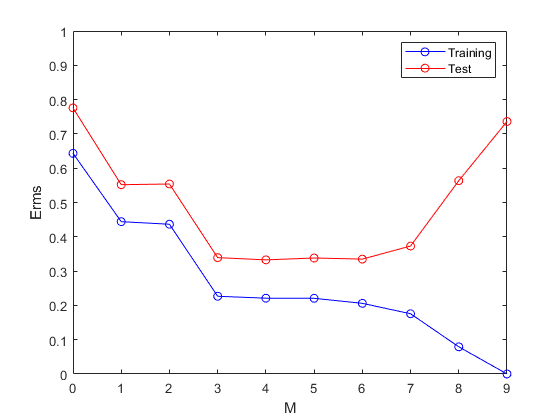

figure,
plot(M, training.rms, 'bO-'),
hold on,
plot(M, test.rms, 'rO-'),
axis([0 9 0 1]),
xlabel('M'), ylabel('Erms'),
legend({'Training', 'Test'});

Generate a table with w coefficients

wTable = table();
wTableVariables = strings(length(W), length(M));
for wi=1:length(W)
    wTableVariables(wi, 1:length(W{wi})) = W{wi};
end
wTable.Variables = wTableVariables';

wTable.Properties.VariableNames = {'M_0', 'M_1', 'M_2', 'M_3', 'M_4', 'M_5', 'M_6', 'M_7', 'M_8', 'M_9'};
wTable

wTable = 10×10 table
       M_0           M_1          M_2            M_3             M_4             M_5            M_6              M_7              M_8               M_9      
    __________    _________    __________    ____________    ____________    ___________    ____________    _____________    _____________    _______________

    "-0.10128"    "0.62812"    "0.49389"     "-0.0412097"    "-0.0945567"    "-0.103186"    "-0.1323427"    "-0.11438887"    "-0.10512131"    "-0.1062604401"
    ""            "-1.4588"    "-0.55273"    "8.25727"       "10.2578"       "11.0439"      "18.82437"      "-0.59129793"    "-66.9158569"    "51.9159148"   
    ""

Plots of the solutions obtained by minimizing the sum-of-squares error function using the M = 9 polynomial for N = 15 data points (left plot) and N = 100 data points (right plot). We see that increasing the size of the data set reduces the over-fitting problem.

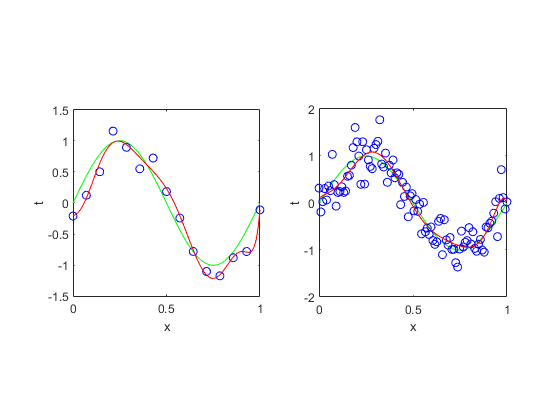

N = [15 100];
figure,
for ni=1:length(N)
    subplot(1, 2, ni),
    plot(x_plot, f(x_plot), 'g'),
    xlabel("x"), ylabel("t"),
    axis square;
    
    m = 9;
    n = N(ni);
    x = linspace(0, 1, n)';
    gaussian = normrnd(0, std, n, 1);
    t = f(x) + gaussian;
    
    hold on,
    plot(x, t, 'bo');
    
    w = min_least_squares(m, x, t);
    trainingModelN = predict(n, w);
    
    hold on,
    plot(x_plot, pol(x_plot, w{1}), 'r');
end